## 实验2：信号的基本绘图

自动2404 毛润泽 2404030220

使用MATLAB绘制以下信号的图表。请将您的代码保存到一个MATLAB脚本文件中，这样您就可以在对文件进行修改后，从MATLAB命令行中重新运行该代码。

使用"subplot"命令可以在同一个页面上绘制多个图表。打印出这些图表，并将其与你的代码一并提交。通过"help subplot"来查找如何使用该命令的相关信息。

使用"plot"命令绘制连续时间信号。使用"stem"命令绘制离散时间信号。

使用"help plot"和"help stem"来了解如何使用这些命令。

我们的约定是f(t)表示连续时间信号，而f(n)表示离散时间信号。

1. 绘制连续时间信号

针对以下任务：运行接下来的三行代码，并解释为什么生成的图表各不相同。

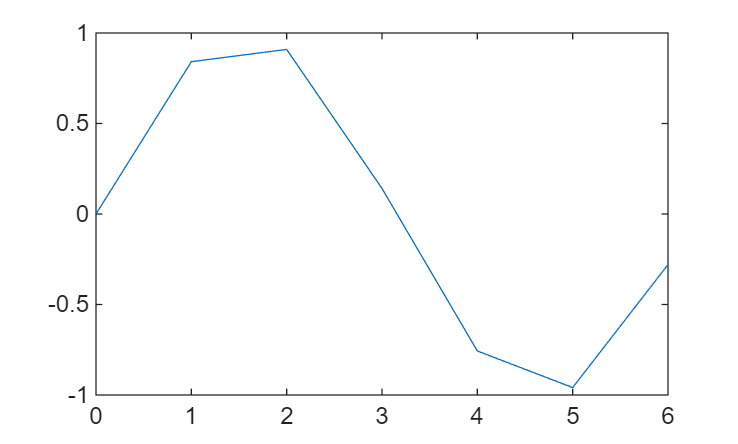

t=0:2*pi;
plot(t,sin(t)) 

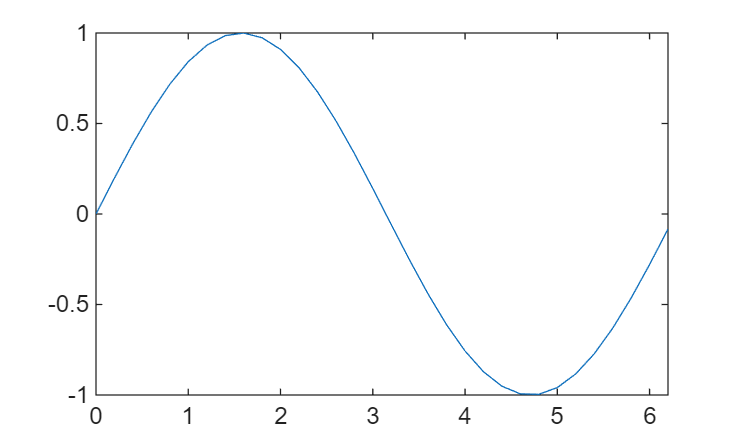

t=0:0.2:2*pi;
plot(t,sin(t)) 

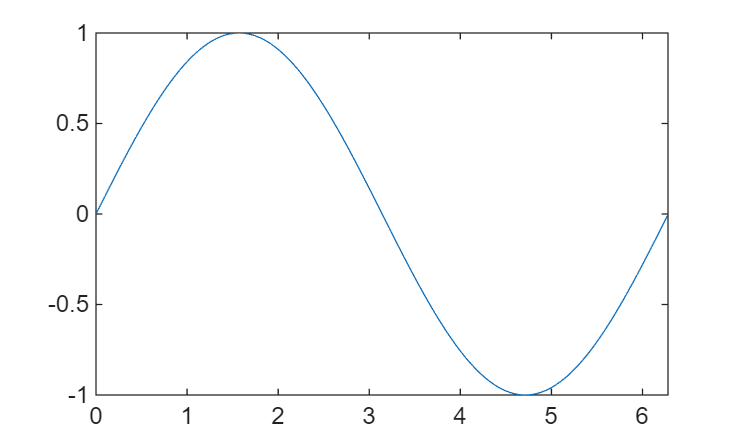

t=0:0.02:2*pi;
plot(t,sin(t))

对于最后一个图表，使用以下命令添加标题和坐标轴标签：

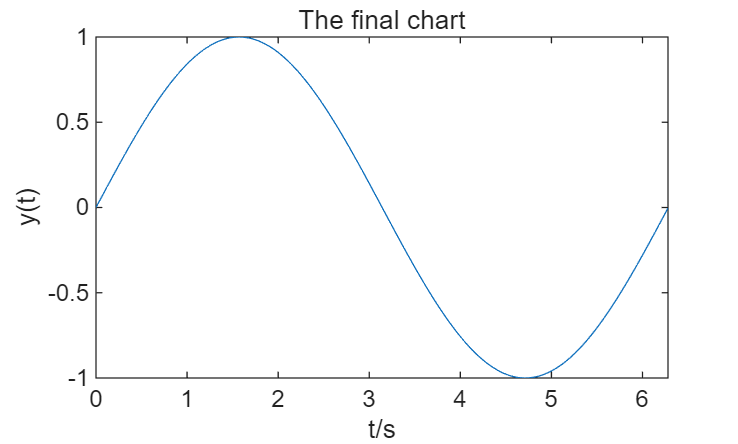

t=0:0.02:2*pi;
plot(t,sin(t))
title('The final chart') 
xlabel('t/s') 
ylabel('y(t)')

更改坐标轴：

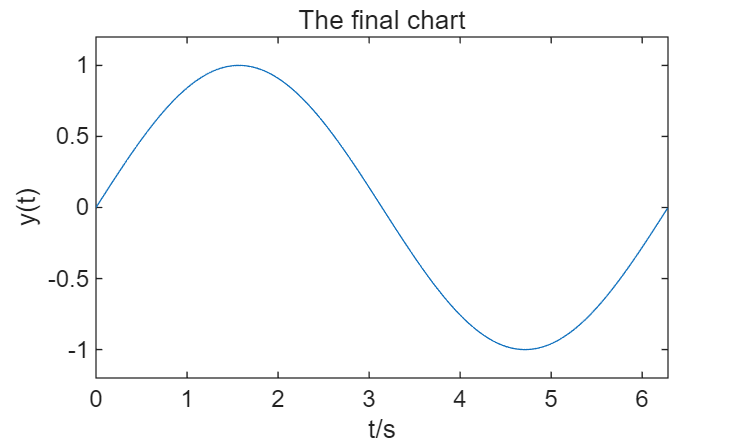

axis([0 2*pi -1.2 1.2]) 

将两个图放在同一个坐标轴上：

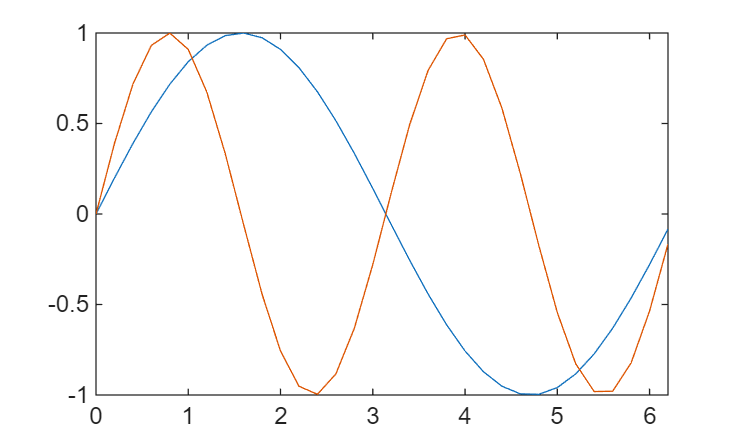

t=0:0.2:2*pi;
plot(t,sin(t),t,sin(2*t))

生成一个不连接数据点的图：

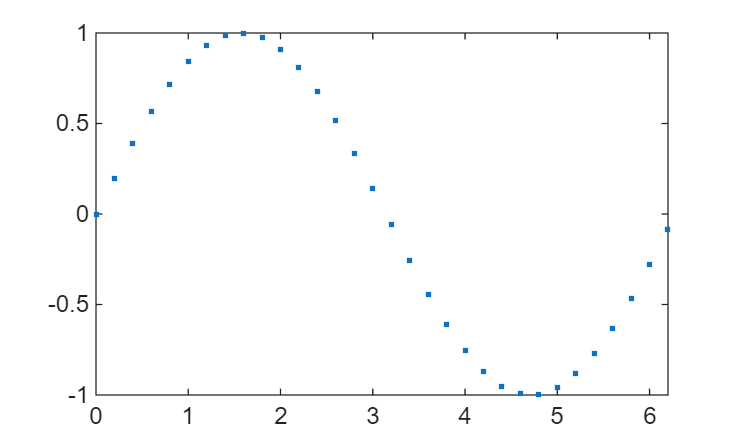

t=0:0.2:2*pi;
plot(t,sin(t),'.')

尝试以下命令：

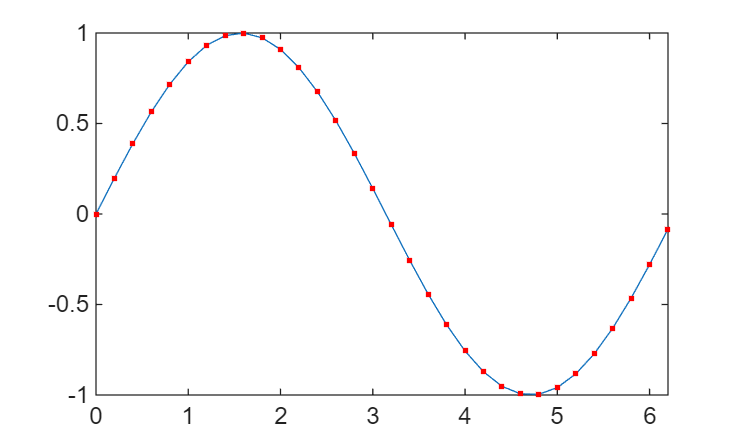

t=0:0.2:2*pi;
plot(t,sin(t),t,sin(t),'r.')

问："r"有什么作用？

答："r"使图像线条为红色,"."使图像上画上点

2.绘制离散时间信号

使用 stem 绘制离散时间阶跃函数：

经典的离散阶跃函数画法

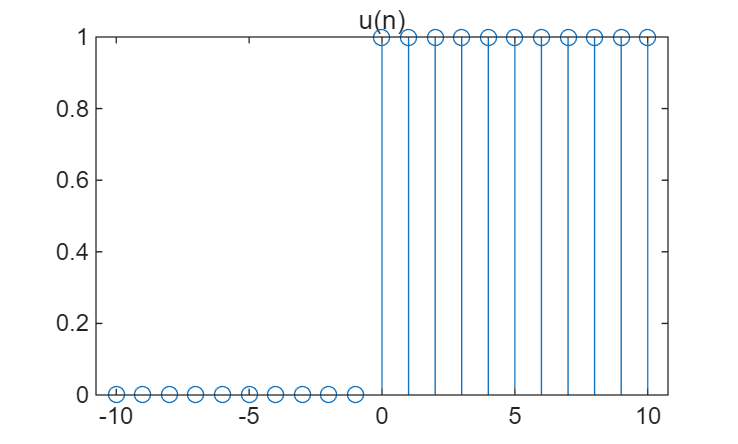

n=-10:10;
f=n>=0;
stem(n,f)
title('u(n)')

绘制下列信号的杆状图（stem plots）。请自行决定 n 的取值范围。

f(n)=u(n)-u(n-4)

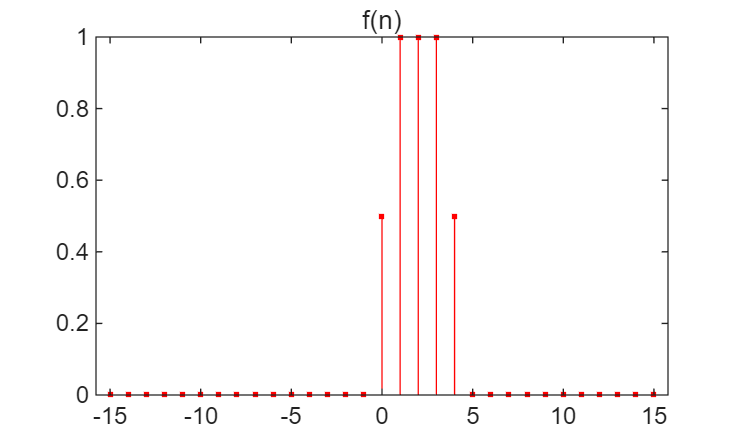

n=-15:15;
fn=heaviside(n)-heaviside(n-4);
stem(n,fn,'r.')
title('f(n)')

注意这里在0出的值，这是与heaviside函数的定义有关，查看matlab帮助，回答原因。

`答：heaviside` 函数用来表示数学中的单位阶跃函数。当输入 `x<0` 时，输出 0；当输入 `x=0` 时，输出 0.5（这是 MATLAB 的默认设定）；当输入 `x>0` 时，输出 1

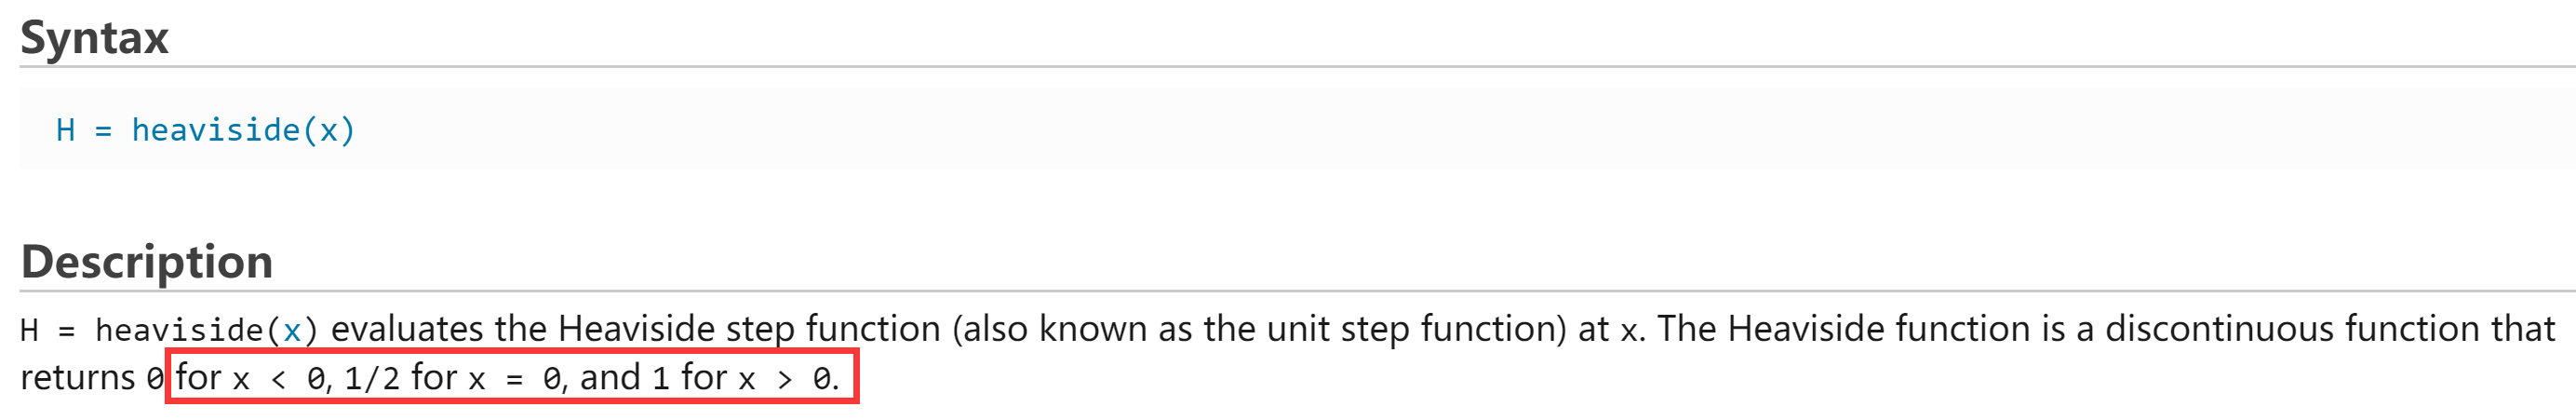

当 x < 0 时返回 0，当 x = 0 时返回 1/2，当 x > 0 时返回 1。

方式1

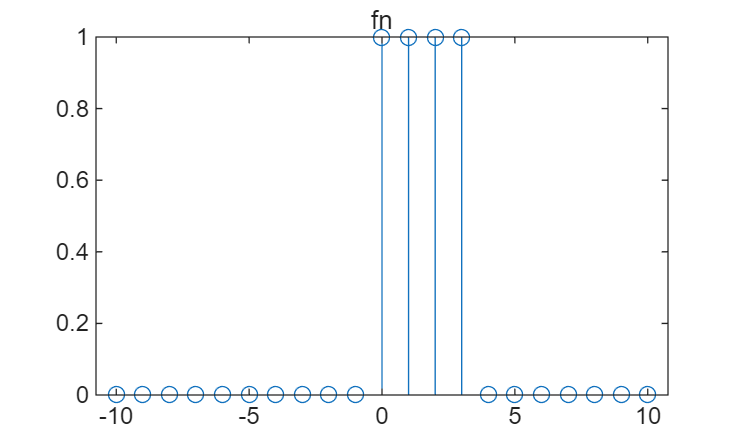

n=-10:10;
f1=n>=0;
f2=n>=4;
fn=f1-f2;
stem(n,fn);
title('fn'); 

方式2

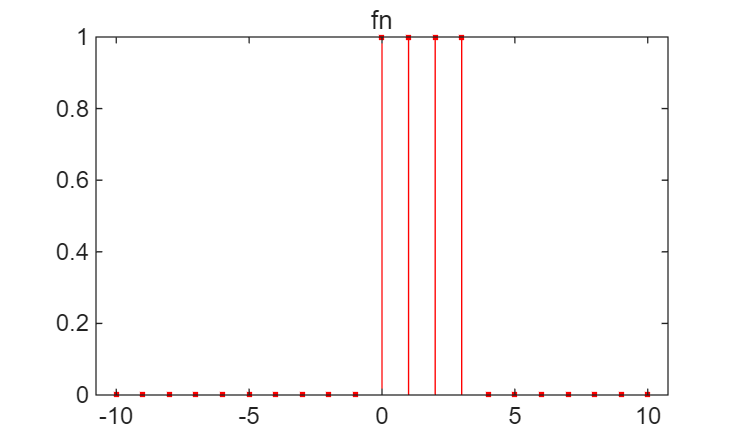

n0=4; ns=-10;nf=10;
n2=ns:nf; 
x1=[zeros(1,-ns),ones(1,nf+1)];  % 离散的单位阶跃函数，即前十个数为0，后十一个数为1
x2=[zeros(1,n0-ns), ones(1,nf-n0+1)]; % 在4处发生跳变的单位阶跃函数
fn=x1-x2;
stem(n2,fn,'r.');title('fn'); 

g(n) = n · u(n) − 2(n − 4) · u(n − 4) + (n − 8) · u(n − 8) 

方式1

clear
n0=4;ns=0;nf=20;
n=ns:nf; 
x1=[zeros(1,-ns),ones(1,nf+1)]; 
f1=n.*x1;
x2=[zeros(1,n0-ns), ones(1,nf-n0+1)]; 
f2=2*(n-4).*x2;
x3=[zeros(1,8-ns), ones(1,nf-8+1)]; 
f3=(n-8).*x3;
gn=n.*x1-2*(n-4).*x2+(n-8).*x3

gn =      0     1     2     3     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0


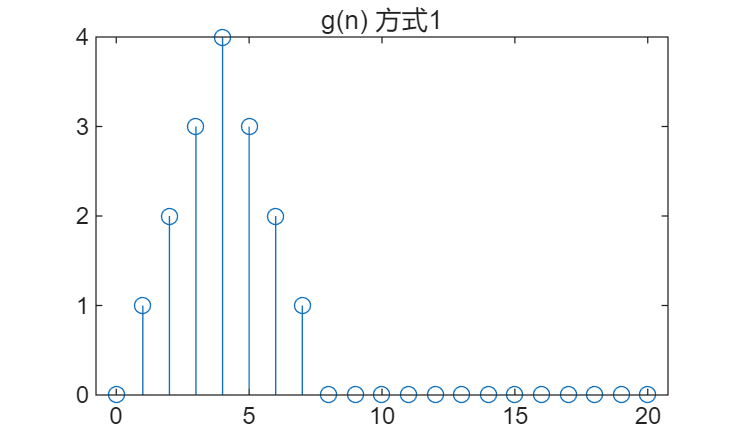

stem(n,gn);
title('g(n) 方式1'); 

方式2

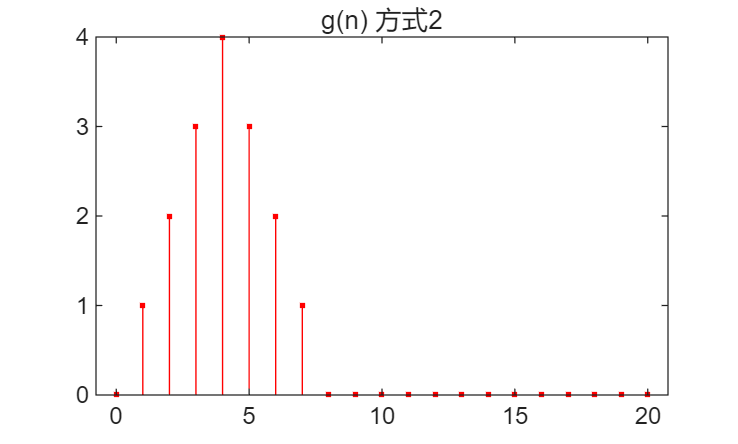

clear
ns=0;nf=20;
n=ns:nf; 
gn=n.*(n>=0)-2.*(n-4).*(n>=4)+(n-8).*(n>=8);
stem(n,gn,'r.');
title('g(n) 方式2'); 

x(n) = δ(n) − 2 δ(n − 4) 

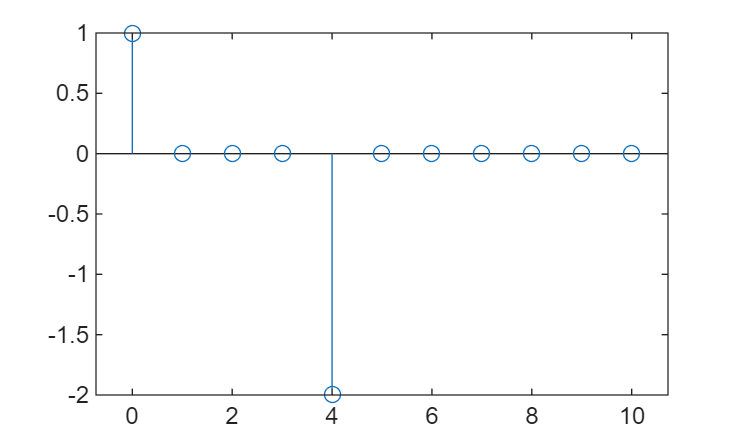

n0=0;n1=4;ns=0;nf=10;
nn=ns:nf; 
x1=[zeros(1,n0-ns),1,zeros(1,nf-n0)];      % x1=[1,0,0,0,0,0,0,0,0,0,0]
x2=[zeros(1,n1-ns),1,zeros(1,nf-n1)];      % x2=[0,0,0,0,1,0,0,0,0,0,0]
stem(nn,x1-2.*x2);

y(n) = (0.9)n (u(n) − u(n − 20)) 

n0=20;ns=0;nf=50;
nn=ns:nf; 
x1=[zeros(1,-ns),ones(1,nf+1)]; 
x2=[zeros(1,n0-ns), ones(1,nf-n0+1)]; 
yn=0.9*nn.*(x1-x2)

yn =          0    0.9000    1.8000    2.7000    3.6000    4.5000    5.4000    6.3000    7.2000    8.1000    9.0000    9.9000   10.8000   11.7000   12.6000   13.5000   14.4000   15.3000   16.2000   17.1000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


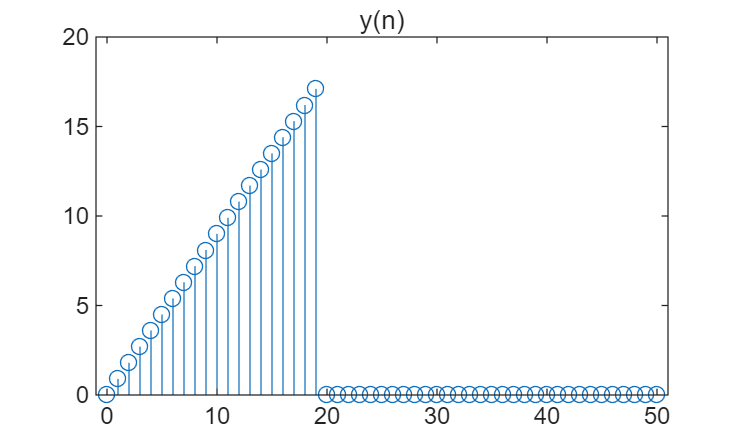

stem(nn,yn);title('y(n)'); 

v(n) = cos(0.12 πn) u(n)

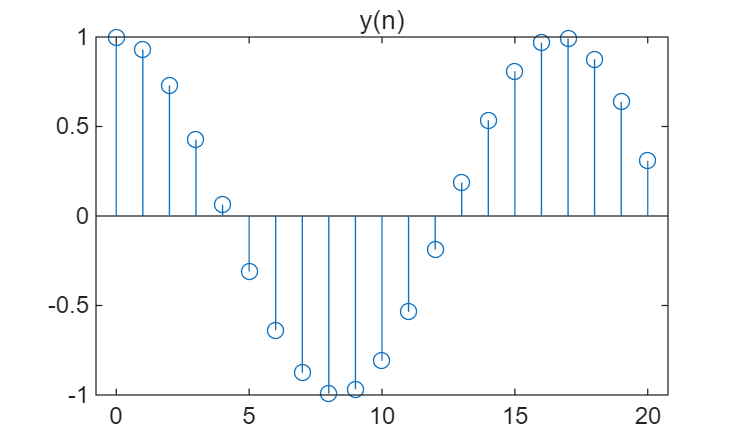

n0=0;ns=0;nf=20;
nn=ns:nf; 
x1=[zeros(1,-ns),ones(1,nf+1)]; 
vn=cos(0.12*pi*nn).*x1;
stem(nn,vn);
title('y(n)'); 

3.conv命令

使用 `help conv` 来了解如何使用 conv 命令。

令

*f*(*n*) = *u*(*n*) − *u*(*n *− 4) 

ns=0;nf=20;
n=[ns:nf];
fn=(n>=0)-(n>=4);

上面有fn

*g*(*n*) = *n *· *u*(*n*) − 2(*n *− 4) · *u*(*n *− 4) + (*n *− 8) · *u*(*n *− 8)*.*

上面有gn

绘制下列卷积的火柴杆图（stem plots）。使用 MATLAB 的 `conv` 命令来计算卷积。

  (a)  f(n) ∗ f(n)

fa=conv(fn,fn)

fa =      1     2     3     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


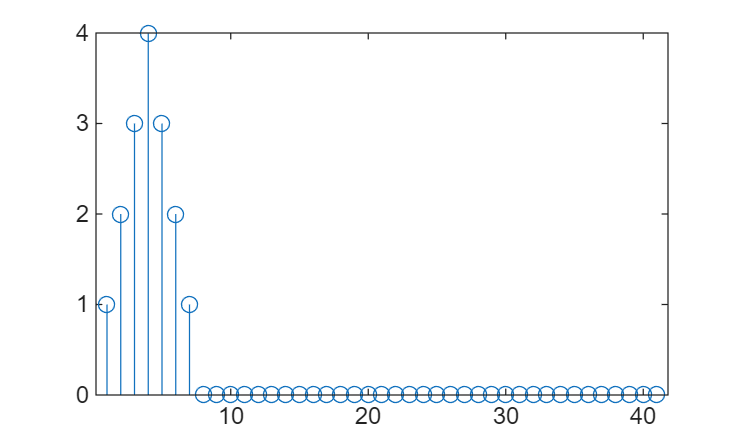

stem(fa)

 (b) f(n) ∗ f(n) ∗ f(n)

fb=conv(fa,fn)

fb =      1     3     6    10    12    12    10     6     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


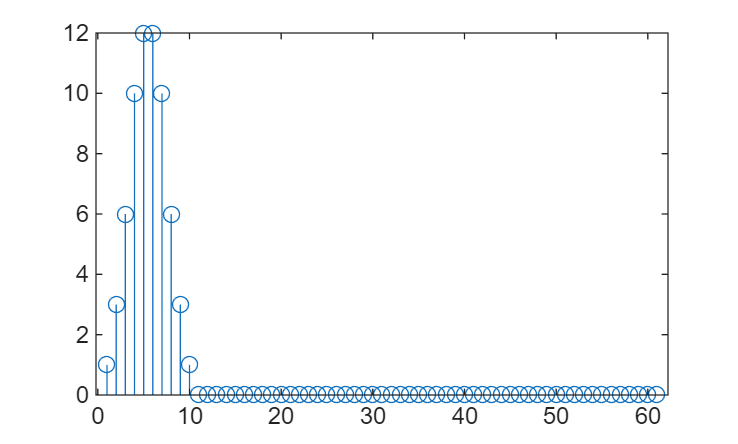

stem(fb)

 (c) f(n) ∗ g(n)

fc=conv(fn,gn)

fc =      0     1     3     6    10    12    12    10     6     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


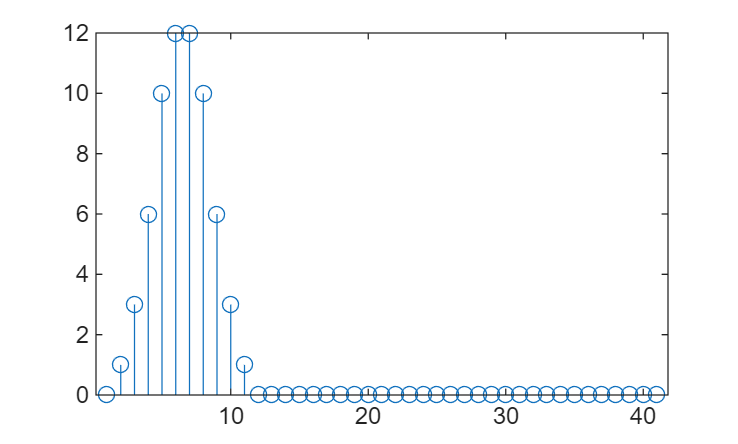

stem(fc)

 (d) g(n) ∗ δ(n) 

fd=conv(gn,x1)

fd =      0     1     3     6    10    13    15    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    15    13    10     6     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0


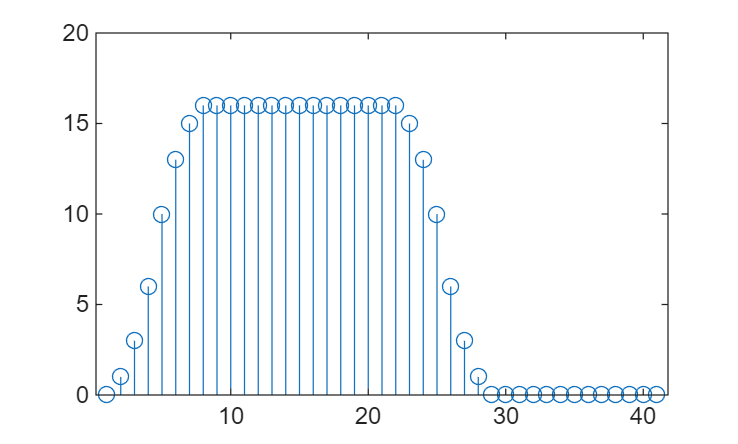

stem(fd)

(e) g(n) ∗ g(n)

fe=conv(gn,gn)

fe =      0     0     1     4    10    20    31    40    44    40    31    20    10     4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


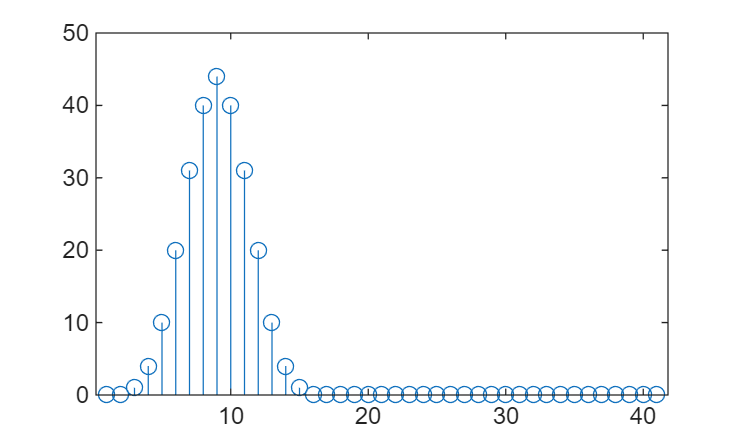

stem(fe)

评论你的观察结果：你是否看到 f(n)∗f(n) 和 g(n) 之间有任何关系？比较 f(n)与 f(n)∗f(n) 以及 f(n)∗f(n)∗f(n) 。当你反复将该信号与自身进行卷积时，会发生什么？

使用命令 `title`、`xlabel`、`ylabel` 来标记你绘图的坐标轴。

答：f(n)∗f(n)和g(n)输出的图像相同，说明两者相等。反复将一个矩形信号与自身进行卷积运算，得到的信号波形会越来越平滑，并逐渐逼近正态分布

4. 绘制采样信号。

假设连续时间信号 x(t)被采样，每个样本之间的采样周期为 0.3 秒。还假设第一个样本是在t=0时采集的，并且总共采集了 12 个样本。下表列出了采集到的 x(t)的样本。

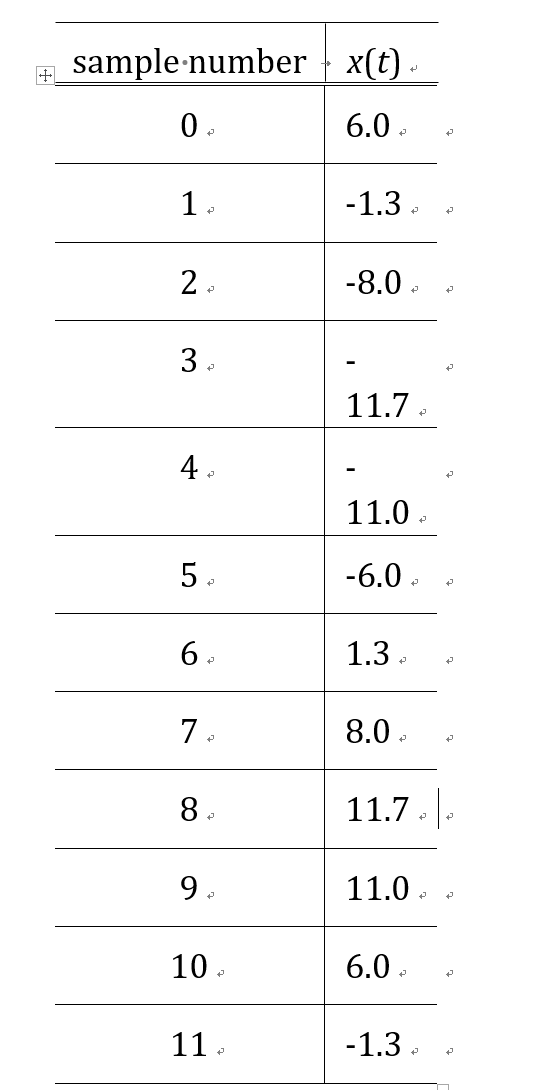

使用 `plot` 命令，绘制该信号的图形。横轴应标记为：（时间（秒））。确保横轴时间轴显示每个样本的正确时间：0, 0.3, 0.6, ..., 3.3。

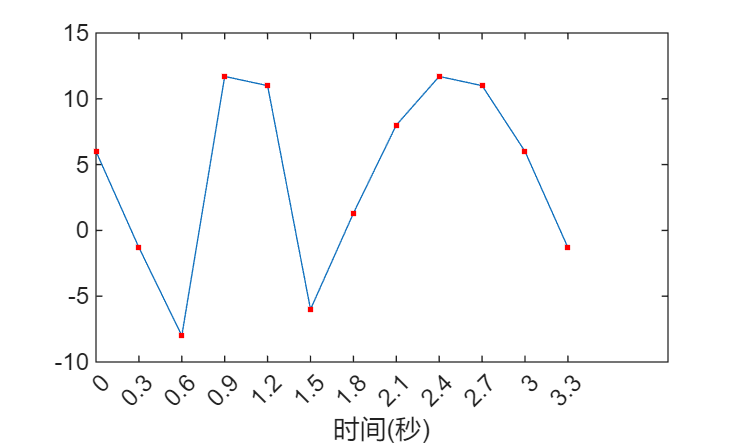

t=0:0.3:5;
xnn=[6 -1.3 -8.0 11.7 11 -6.0 1.3 8.0 11.7 11 6 -1.3];
tt=t(1,1:12);   %截取t的前12个点
plot(t(1,1:12),xnn,t(1,1:12),xnn,'r.')
xticks([0    0.3000    0.6000    0.9000    1.2000    1.5000    1.8000    2.1000    2.4000    2.7000    3.0000    3.3000]);
xlabel('时间(秒)')

实验总结：通过 Lab 2，我学会了如何利用 MATLAB 进行信号的基本绘图与处理。我掌握了连续时间信号与离散时间信号的绘制方法，理解了采样间隔对信号显示效果的影响，并学会了使用 `plot` 和 `stem` 命令进行可视化。通过构建单位阶跃函数 u(n)和单位脉冲函数 δ(n)，我能够生成复杂的离散序列，并运用 `conv` 命令计算卷积，观察信号在时域中的相互作用。此外，我还掌握了如何通过 `subplot`、`title`、`axis` 等命令修饰图形，使结果更加清晰直观，为后续的信号分析实验打下了坚实基础。